% generate some random data 
x = -20:20;
y = 1.5*x.^2 - 60*x + 10 + 123*randn(size(x));

% given these data, we will now try to fit a model % to the data.  we assume we know what model to use, % namely, y = ax^2 + bx + c where a, b, and c are % free parameters.  notice that this was the model % we used to generate the data.
% since our model is a linearized model, we can express % it using simple matrix notation.
% construct the regressor matrix 
X = [x(:).^2 x(:) ones(length(x),1)];
% estimate the free parameters of the model 
% % using ordinary least-squares (OLS) estimation 
% https://en.wikipedia.org/wiki/Ordinary_least_squares
w = inv(X'*X)*X'*y(:);
% what are the estimated weights? 
w

w =     1.7051
  -60.3636
  -30.5903


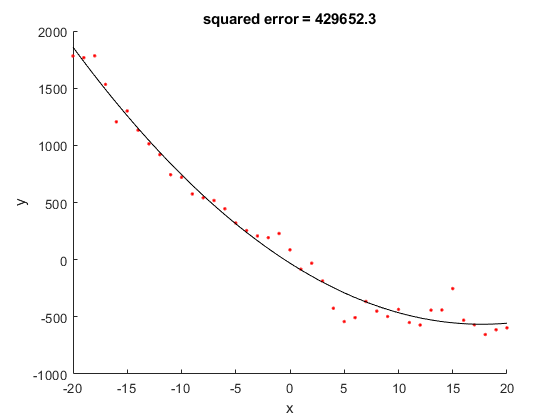


% what is the model fit?
modelfit = X*w;

% what is the squared error achieved by this model fit?
squarederror = sum((y(:)-modelfit).^2);

%visualize
figure;
hold on;
% real data
scatter(x,y,'r.');

ax = axis;
xx = linspace(ax(1),ax(2),100)';
yy = [xx.^2 xx ones(length(xx),1)]*w;
plot(xx,yy,'k-');
xlabel('x');
ylabel('y');
title(sprintf('squared error = %.1f',squarederror));

% Example 2. Fit a parametric nonlinear model

% generate some random data

x = 0:.05:3;
y = 5*x.^3.5 + 5*randn(size(x));

% give n these data, we will now try to fit a model
% to the data. We assume we know what model to use,
% namely, y = ax^n where a and n are free parameters.
% Notice that this was the model we used to generate the data


% define optimization options
options = optimset('Display','iter','FunValCheck','on', ...
    'MaxFunEvals',Inf,'MaxIter',Inf, ...      
    'TolFun',1e-6);

% define bounds for the parameters
%              a    n
paramslb = [-inf    0];    % lower bound
paramsub = [inf     inf];   % upper bound

% define the initial seed
%          a    n
params0 = [1    1];

% estimate the free parameters of the model using nonlinear optimization
    % hist: pp is a vector of parameters like [a n],
    %       xx is a vector of x-values like [.1 .4 .5],
    %       and what modelfun does is to output the predicted y-values.
    % 
    % 
    % 
modelfun = @(pp, xx) pp(1)*xx.^pp(2);

[params, resnorm, residual, exitflag, output] = lsqcurvefit(modelfun, params0, x,y, paramslb, paramsub, options);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          3          423211                      7.77e+03
     1          6          423211             10       7.77e+03      
     2          9          240154            2.5       8.22e+04      
     3         12          240154         2.9121       8.22e+04      
     4         15         87771.2       0.728025       1.06e+05      
     5         18         8848.18        1.53168        2.4e+05      
     6         21         1380.22       0.346683       8.96e+03      
     7         24          1313.2       0.373034       1.48e+03      
     8         27          1307.3       0.050009             23      
     9         30          1307.3    0.000539161         0.0625      

Local minimum possible.

lsqcurvefit stoppe

% what are estimated parameters?
params

params =     4.6391    3.5759


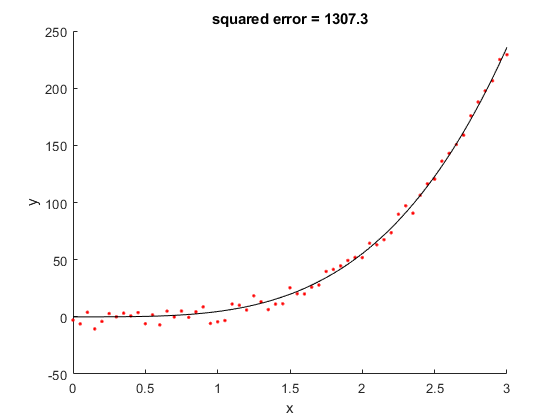


% What is the model fit?
modelfit = modelfun(params, x);

% what is the squared error achieved by this model fit?
squarederror = sum((y(:) - modelfit(:)).^2);
% note that the resnorm output also provides the squared error.


%visualize
figure;
hold on;
scatter(x,y,'r.');

ax = axis;

xx = linspace(ax(1),ax(2),100)';
yy = modelfun(params,xx);

plot(xx,yy,'k-');
xlabel('x');
ylabel('y');
title(sprintf('squared error = %.1f', squarederror));

% Example 3.  Another optimization example

x = rand(1,1000).^2;

% we want to determine the value that minimizes the sum of the absolute
% differences between the value and the data points

% define some stuff
options = optimset('Display','iter','FunValCheck','on', ...
    'MaxFunEvals',Inf,'MaxIter',Inf, ...
    'TolFun', 1e-6, 'TolX', 1e-6);

paramslb = []; % [] means no bounds;
paramsub = [];
params0 = [0];

% perform the optimization

    % hint: here we have to apply a square root transformation so that when
    % lsqnonlin squares the output of costfun, we will be back to absolute
    % error.
    
costfun = @(pp) sqrt(abs(x-pp));

[params, resnorm, residual, exitflag, output] = lsqnonlin(costfun, params0, paramslb, paramsub, options);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          2         340.738                           500
     1          4         340.653    8.61225e-05            489      
     2          6         336.532     0.00447906            438      
     3          8         328.596     0.00967101            386      
     4         10         311.635      0.0247839            307      
     5         12         296.613      0.0279088            237      
     6         14         285.103      0.0265989            195      
     7         16         269.682      0.0452021            141      
     8         18          263.47      0.0271086             96      
     9         20         259.907      0.0206942             77      
    10         22          256.99      0.0212011             60      
    11         24         255.411      0.0152952             41      
    12         26         255.19

% what is the solution?
params

params = 0.2543


% what is the median of the data?
median(x)

ans = 0.2545


% notice that the solution is nearly identical to the median of the data.
% (the slop comes from the tolerance used in the optimization and from the
% iterpolation used in the calculation of the median.)